#              Antenna Array Processing

###                                            HW1

     Mohammadreza Arani         :::::::::::::         810100511

                                             1401/07/26                                         

clear; clc; close all;

## Question 1: EEG Problem


Num_of_channel = 16;
K_timewin = 11;
T_win_sample = 100 ;


Num_of_sources_k  = 2+ abs((1:K_timewin)-6) ;

A = cell(1,K_timewin)  ;
S =A;  RS = A ; RL =A; RN = A; Noise = A; X=A;

    % Part 1:
for i=1:K_timewin
    A{i}  = randn(Num_of_channel , Num_of_sources_k(i)) ;
end

    % Part 2:

fs  = 20e3; % Sampling Freq
Ts = 1/fs;

for i=1:K_timewin 
    f = (1:Num_of_sources_k(i))*1e3 ;
    t = ((i-1)*T_win_sample:i*T_win_sample-1)*Ts;
    S{i} = cos(2*pi*f'*t) ;
    RS{i}  = S{i}*S{i}'/T_win_sample ;


end

% To see RS:
disp(RS{randi(K_timewin)})

    0.5000   -0.0000    0.0000   -0.0000    0.0000
   -0.0000    0.5000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.5000    0.0000   -0.0000
   -0.0000    0.0000    0.0000    0.5000    0.0000
    0.0000    0.0000   -0.0000    0.0000    0.5000



We can see that as expected RS includes  diagonal Matrix!

    % Part 3:

for  i = 1:K_timewin     
    RL{i} = A{i}*RS{i}*A{i}.' ; % Quadratic form to formulate RL
    RL_rank = rank(RL{i});
    disp("Rank of RL{"+i+"}"+" = "+RL_rank+...
                " (M("+i+") = "+Num_of_sources_k(i)+" )")
end

Rank of RL{1} = 7 (M(1) = 7 )
Rank of RL{2} = 6 (M(2) = 6 )
Rank of RL{3} = 5 (M(3) = 5 )
Rank of RL{4} = 4 (M(4) = 4 )
Rank of RL{5} = 3 (M(5) = 3 )
Rank of RL{6} = 2 (M(6) = 2 )
Rank of RL{7} = 3 (M(7) = 3 )
Rank of RL{8} = 4 (M(8) = 4 )
Rank of RL{9} = 5 (M(9) = 5 )
Rank of RL{10} = 6 (M(10) = 6 )
Rank of RL{11} = 7 (M(11) = 7 )


As it apears, Rank of RL is the same as Num_of_sources used to produce the signal at interval K! 

    % Part 4:

 Sigma_2 = rand()+1;
 rho = 0.2*Sigma_2;
 Rn = eye(Num_of_channel)*Sigma_2;
 Rn(1:end-1 , 2:end)  = Rn(1:end-1 , 2:end) + eye(Num_of_channel-1)*rho ;
 Rn(2:end , 1:end-1)  = Rn(2:end , 1:end-1) + eye(Num_of_channel-1)*rho ;

    % Part 5:
[W , Lambda]  = eig(Rn);

for i=1:K_timewin
    Noise{i} = repmat(sqrt( diag(Lambda) ), 1,T_win_sample).*randn(Num_of_channel , T_win_sample)  ;
    Noise{i} = W*Noise{i};
    RN{i} = Noise{i}*Noise{i}.'/T_win_sample;
end
disp(RN{randi(max(Num_of_sources_k))})

  Columns 1 through 10

    1.6889    0.1801   -0.2608   -0.1725    0.1978   -0.0235   -0.1619   -0.0959   -0.0937    0.0336
    0.1801    1.1695    0.2838    0.0618   -0.0486   -0.0061   -0.0621    0.1000    0.0130    0.1510
   -0.2608    0.2838    1.1429    0.3825   -0.1802   -0.0952   -0.1284   -0.1032   -0.0297   -0.1236
   -0.1725    0.0618    0.3825    1.3825    0.3333    0.0556   -0.0971    0.0732   -0.1679   -0.0541
    0.1978   -0.0486   -0.1802    0.3333    1.4137    0.3458    0.0623   -0.0111   -0.0260   -0.0447
   -0.0235   -0.0061   -0.0952    0.0556    0.3458    1.3338    0.3687    0.1688    0.0125    0.1667
   -0.1619   -0.0621   -0.1284   -0.0971    0.0623    0.3687    1.1760    0.1710   -0.0875   -0.0042
   -0.0959    0.1000   -0.1032    0.0732   -0.0111    0.1688    0.1710    1.3697    0.2527    0.0440
   -0.0937    0.0130   -0.0297   -0.1679   -0.0260    0.0125   -0.0875    0.2527    1.4461    0.1009
    0.0336    0.1510   -0.1236   -0.0541   -0.0447    0.1667   -0.0

% Try previous Part with a bigger T_Win:

T_win_sample_2  =1e6;

% Part 5:
[W , Lambda]  = eig(Rn);
Noise2 = Noise;
RN2 = RN;

for i=1:K_timewin
    Noise2{i} = repmat(sqrt( diag(Lambda) ), 1,T_win_sample_2).*randn(Num_of_channel , T_win_sample_2)  ;
    Noise2{i} = W*Noise2{i};
    RN2{i} = Noise2{i}*Noise2{i}.'/T_win_sample_2;
end
disp(RN{randi(max(Num_of_sources_k))})

  Columns 1 through 10

    1.3580    0.2190   -0.0930    0.0136   -0.0994   -0.1621   -0.1450   -0.0556    0.0331   -0.0006
    0.2190    1.3731    0.2923   -0.0056   -0.1175    0.0954    0.1227   -0.1847   -0.1794   -0.0683
   -0.0930    0.2923    1.5339    0.4065   -0.0640    0.0569   -0.0769   -0.3293   -0.4331   -0.2314
    0.0136   -0.0056    0.4065    1.2986    0.2251    0.1024    0.0151    0.0776   -0.1114   -0.1526
   -0.0994   -0.1175   -0.0640    0.2251    1.1478    0.3337   -0.1381    0.0526    0.0761   -0.0140
   -0.1621    0.0954    0.0569    0.1024    0.3337    1.2212    0.1232    0.0342    0.0696    0.1814
   -0.1450    0.1227   -0.0769    0.0151   -0.1381    0.1232    1.4009    0.4502   -0.0522    0.1658
   -0.0556   -0.1847   -0.3293    0.0776    0.0526    0.0342    0.4502    1.3729    0.1039    0.0771
    0.0331   -0.1794   -0.4331   -0.1114    0.0761    0.0696   -0.0522    0.1039    1.3945    0.4705
   -0.0006   -0.0683   -0.2314   -0.1526   -0.0140    0.1814    0.1

    % Part 6:

for i=1:K_timewin    
        X{i} =  A{i}*S{i} + Noise{i} ;
end


### Question 2:  Antenna Array Problem

#### Part 1:

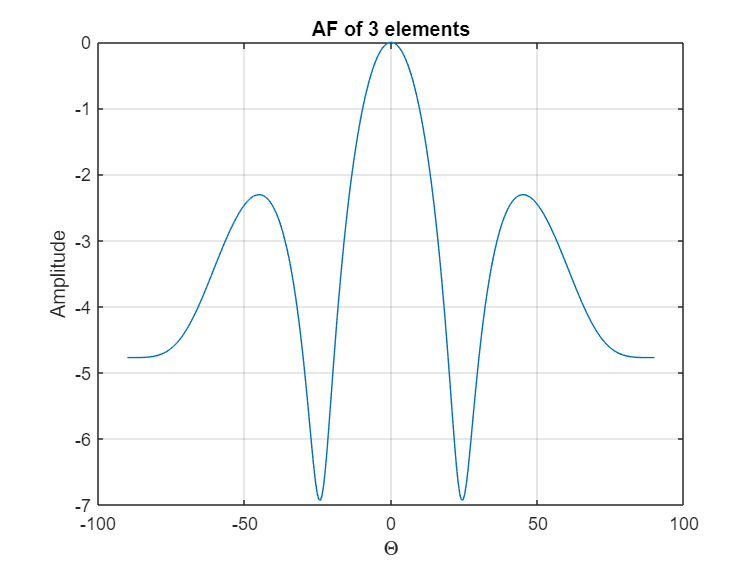

clear;

N = 3;  % a horizontal Array

d1 = 2; d2 = 4; d3 =5; % Height of each element:::meter
D=[d1,d2,d3];
W = ones(1,length(D)) ;

fc = 150e6; % 150MHz
c = 3e8;
k = 2*pi*fc/c ;

theta = -pi/2:0.01:pi/2 ;

AF  = abs(W*exp(1j*k*D'*sin(theta))  );

figure()
plot(180/pi*theta , db(sqrt(AF/max(AF) ) )    ) % AF with Normaliztion
grid on
title("AF of "+length(W)+" elements")
xlabel("\Theta")
ylabel("Amplitude")

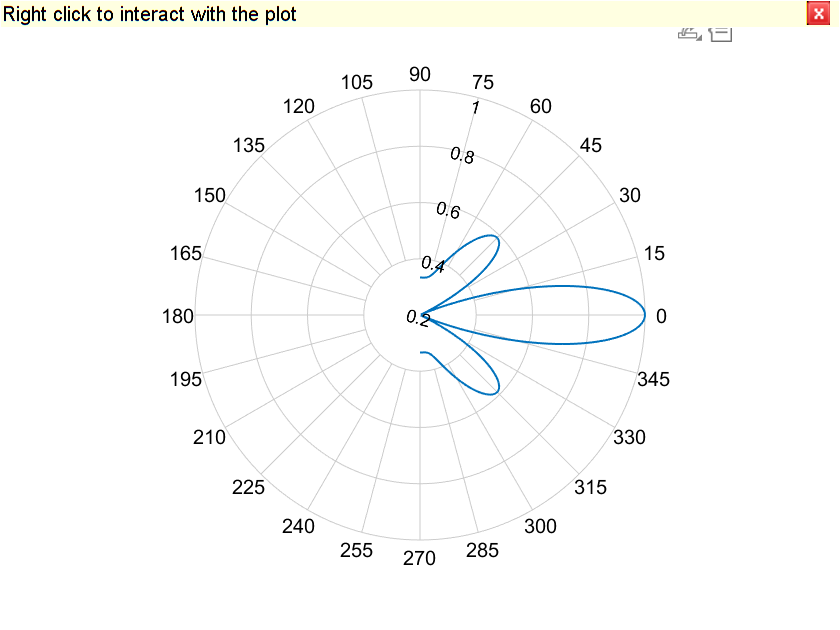

figure()
polarpattern(theta*180/pi,AF/max(AF));

#### Part 2:

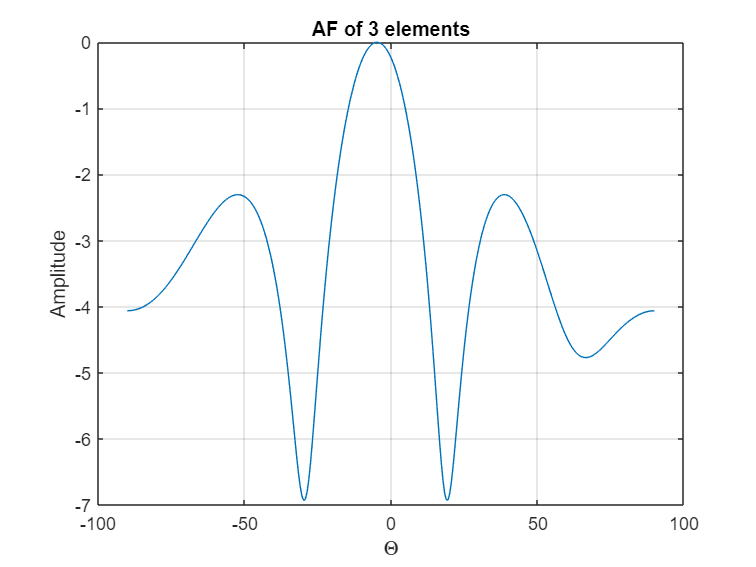


phase_diff = [0,30,45];

AF_2  = abs(exp(1j*pi*phase_diff/180).*W*exp(1j*k*D'*sin(theta))  );

figure()
plot(180/pi*theta , db(sqrt(AF_2/max(AF_2) ) )    ) % AF with Normaliztion
grid on
title("AF of "+length(W)+" elements")
xlabel("\Theta")
ylabel("Amplitude")

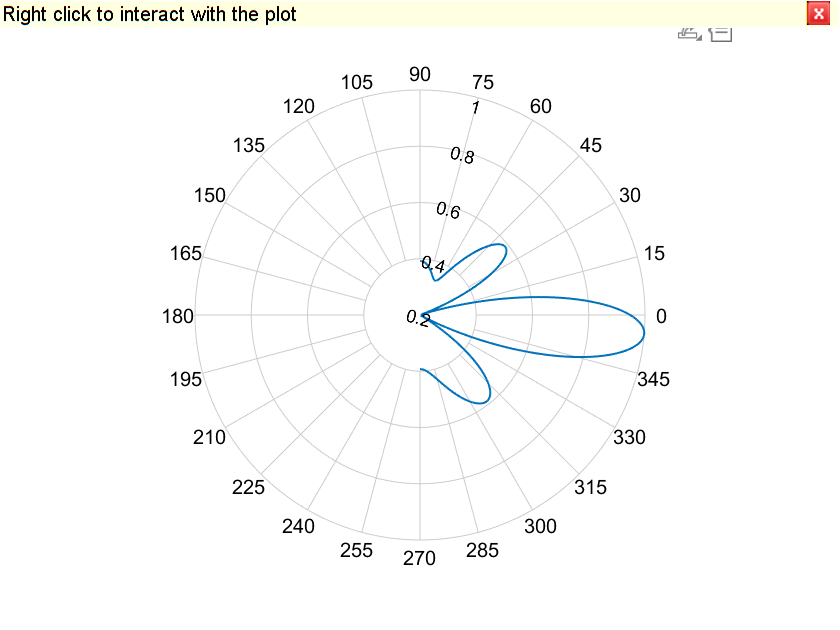


figure()
polarpattern(theta*180/pi,AF_2/max(AF_2));

#### Part 3:

phi_2 = -90:1:90 ;
phi_3 = phi_2;

[PHI_2 , PHI_3] = meshgrid(phi_2,phi_3);

fun  = @(phi1,phi2) Array_factor(phi1,phi2)

fun = function_handle with value:
    @(phi1,phi2)Array_factor(phi1,phi2)



figure()
h=surf( PHI_2  ,  PHI_3  ,  arrayfun( @(x,y)fun(x,y)  ,  PHI_2 ,PHI_3)      )

h =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [181×181 double]
           YData: [181×181 double]
           ZData: [181×181 double]
           CData: [181×181 double]

  Show all properties


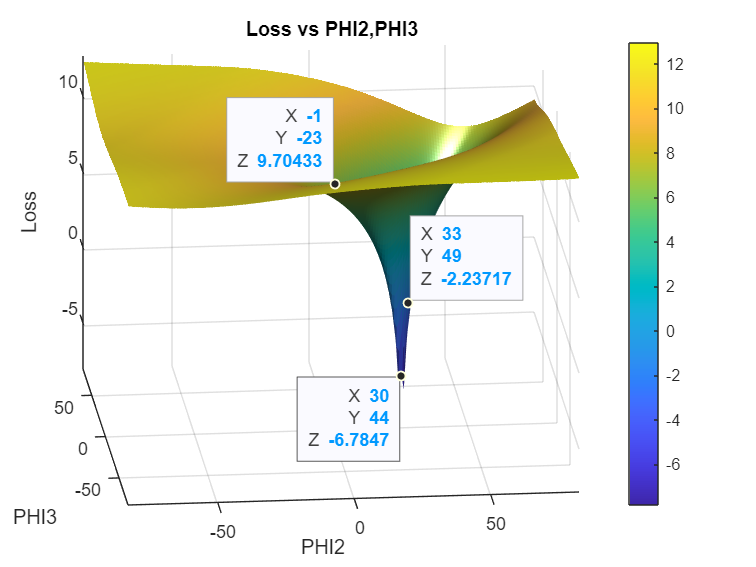

xlabel('PHI2');
ylabel('PHI3');
zlabel('Loss');
title("Loss vs PHI2,PHI3")
set(h,'LineStyle','none')
camlight
colorbar

fun(30,45)

ans = -Inf

It can be seen that the answer is unique for this problem, but it will not be assured to have a unique answer for other problems as well!

a limited 3 element array, produced an array factor and without changing the design and weights, we have steered the array so to change the direction of the pattern! =>

There will be just 1 answer for this problem due to stability of all other variables and changing just the array factor phase of 2 elements simulating a beam-steering!

function Loss = Array_factor(phi1,phi2)
   
    N = 3;  % a horizontal Array

    d1 = 2; d2 = 4; d3 =5; % Height of each element:::meter
    D=[d1,d2,d3];
    W = ones(1,length(D)) ;
    
    fc = 150e6; % 150MHz
    c = 3e8;
    k = 2*pi*fc/c ;
    theta = -pi/2:0.01:pi/2 ;
    phase_diff = [0,30,45];

    AF_2  = abs(exp(1j*pi*phase_diff/180).*W*exp(1j*k*D'*sin(theta))  );

   AF = abs(exp(1j*pi*[0,phi1,phi2]/180).*W*exp(1j*k*D'*sin(theta))  );
   Loss = db(sqrt(norm(AF - AF_2 ))); % L2 Norm 
   %obj = x(1)*a + x(2)^2*b + c;
end

%%








